clear
clc

rpm=linspace(0,90,181);
w=2*pi*rpm/60;
h=0.5;
L=2.31;
n=linspace(0,5,201);

H_tank=TF_tank(w,h);
[w_res,H_res]=TF_res(n,L,h);
rpm_res=60*w_res/(2*pi);

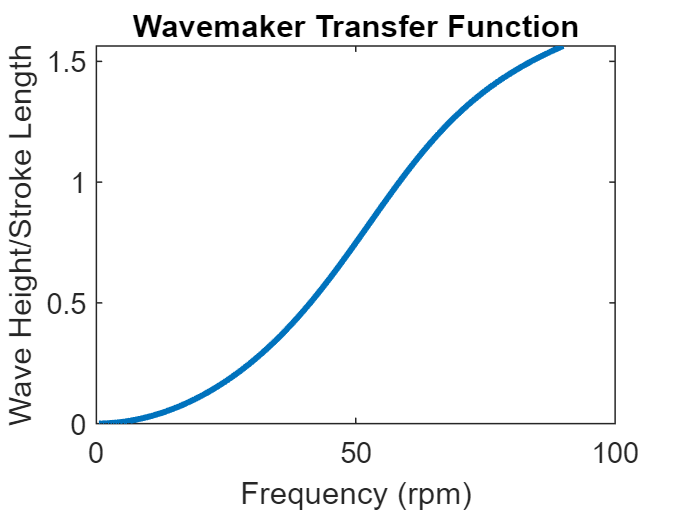

figure
plot(rpm,H_tank,'LineWidth',2)
xlabel('Frequency (rpm)')
ylabel('Wave Height/Stroke Length')
title('Wavemaker Transfer Function')

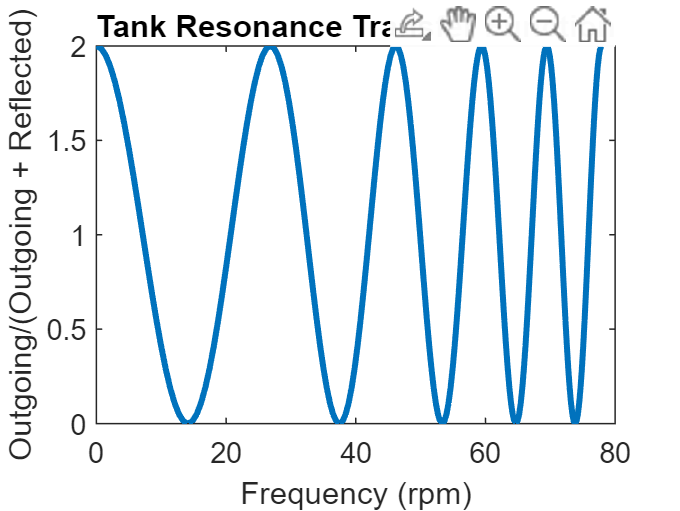

figure
plot(rpm_res,H_res,'LineWidth',2)
xlabel('Frequency (rpm)')
ylabel('Outgoing/(Outgoing + Reflected)')
title('Tank Resonance Transfer Function')

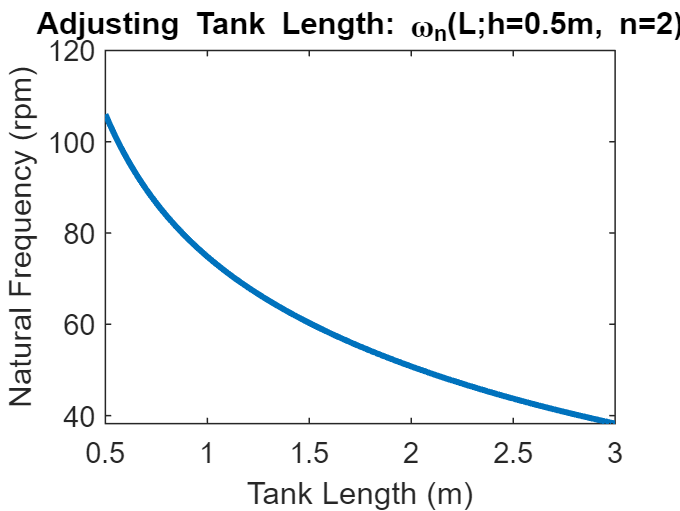

%examining changing length vs height
n=2;
h=0.5;
L=linspace(0.5,3,101);
[w_L,~]=TF_res(n,L,h);
rpm_L=60*w_L/(2*pi);

figure
plot(L,rpm_L,'LineWidth',2)
xlabel('Tank Length (m)')
ylabel('Natural Frequency (rpm)')
title('Adjusting Tank Length: \omega_n(L;h=0.5m, n=2)')

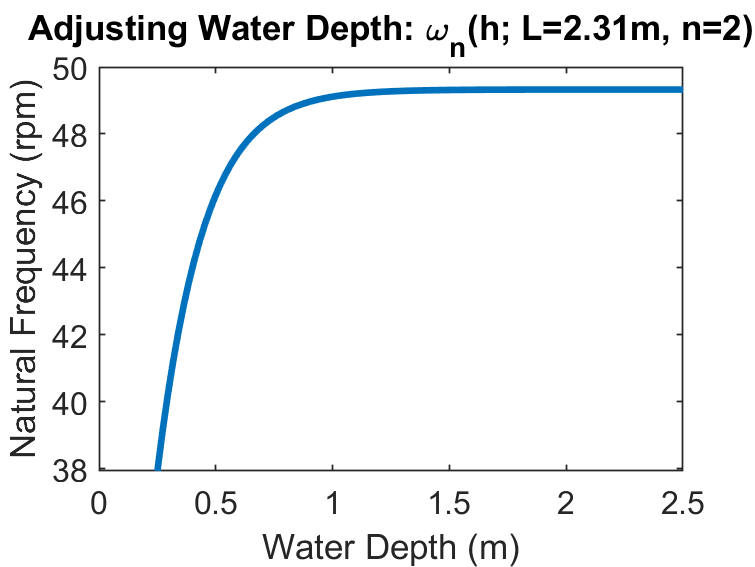


n=2;
L=2.31;
h=linspace(0.25,2.5,101);
[w_h,~]=TF_res(n,L,h);
rpm_h=60*w_h/(2*pi);

figure
plot(h,rpm_h,'LineWidth',2)
xlabel('Water Depth (m)')
ylabel('Natural Frequency (rpm)')
title('Adjusting Water Depth: \omega_n(h; L=2.31m, n=2)')

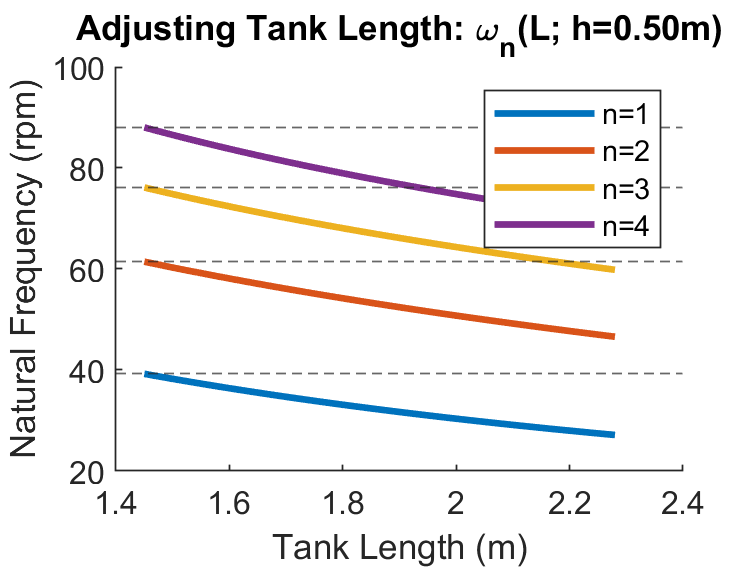

figure
hold on

lim_vals=zeros(1,4);
for n=1:4
    h=0.5;
    L=linspace(1.45,2.28,101);
    
    [w_L,~]=TF_res(n,L,h);
    rpm_L=60*w_L/(2*pi);
    
    plot(L,rpm_L,'LineWidth',2)
    lim_vals(n)=rpm_L(1);
end
for n=1:4
    yline(lim_vals(n),'LineStyle','--')
end
hold off
xlabel('Tank Length (m)')
ylabel('Natural Frequency (rpm)')
title('Adjusting Tank Length: \omega_n(L; h=0.50m)')
legend('n=1','n=2','n=3','n=4')

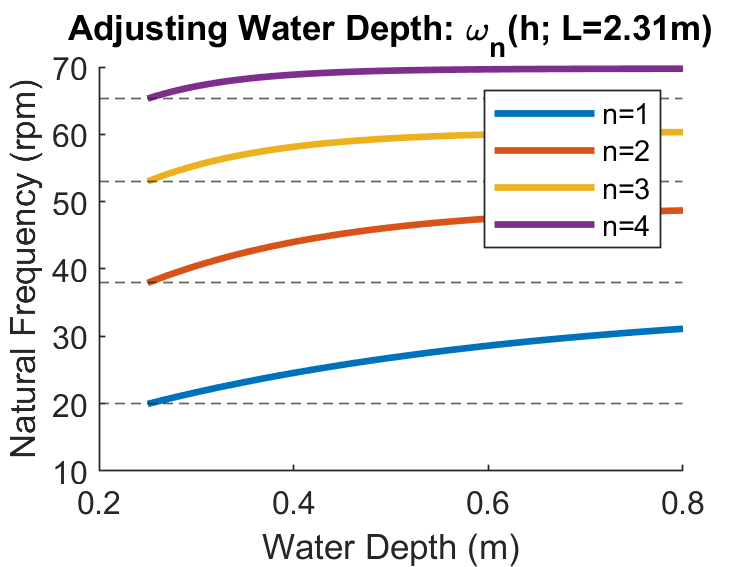


figure
hold on

lim_vals=zeros(1,4);
for n=1:4
    L=2.31;
    h=linspace(0.25,0.8,101);
    [w_h,~]=TF_res(n,L,h);
    rpm_h=60*w_h/(2*pi);
    
    plot(h,rpm_h,'LineWidth',2)
    lim_vals(n)=rpm_h(1);
end
for n=1:4
    yline(lim_vals(n),'LineStyle','--')
end
hold off
xlabel('Water Depth (m)')
ylabel('Natural Frequency (rpm)')
title('Adjusting Water Depth: \omega_n(h; L=2.31m)')
legend('n=1','n=2','n=3','n=4')